# Voltage clamp

Hodgkin and Huxley analyzed the squid giant axon using the then-recently-invented voltage clamp. A voltage clamp allows us to hold the membrane potential of a cell approximately constant and watch how the currents change. NEURON comes with two voltage clamp mechanisms, `VClamp` for two-electrode clamps, and `SEClamp` for the single electrode.

Here, we'll observe how sodium and potassium currents change in response to a voltage clamp experiment.

## Get started

To get started we must create our NEURON object and load `stdrun.hoc`. Just to be safe, we'll also clear all MATLAB values and discard any existing sections.

clear;
n = neuron.start_session();     % Initialize the NEURON session.
n.reset_sections();             % Reset topology.
n.load_file("stdrun.hoc");      % load the standard run control

## The model

We'll create a single point soma with Hodgkin-Huxley dynamics:

soma = n.Section("soma");
soma.length = 10;
soma.set_diameter(10);
soma.insert("hh");

## The recording

We'll record the sodium current `ina` and the potassium current `ik`. This requires a `Vector` for each:

ina = n.Vector();
ina.record(soma(0.5).ref("ina"));
ik = n.Vector();
ik.record(soma(0.5).ref("ik"));

It's also a good idea to record time:

t = n.Vector();
t.record(n.ref("t"));

When using a fixed step solver (NEURON's default), we could calculate t values after the fact since we know the step stize, but NEURON also supports a variable step solver, so by just storing t from the beginning, we'll have code that will work in the future if we decide we want to use a variable step solver.

## The experiment

Let's create a single electrode voltage clamp.

seclamp = n.SEClamp(soma(0.5));
seclamp.amp1 = -65;
% seclamp.amp2 will be our test voltage
seclamp.amp3 = -65;
seclamp.dur1 = 10;
seclamp.dur2 = 30;
seclamp.dur3 = 10;

Now we run the experiment for several different choices of `seclamp.amp2`:

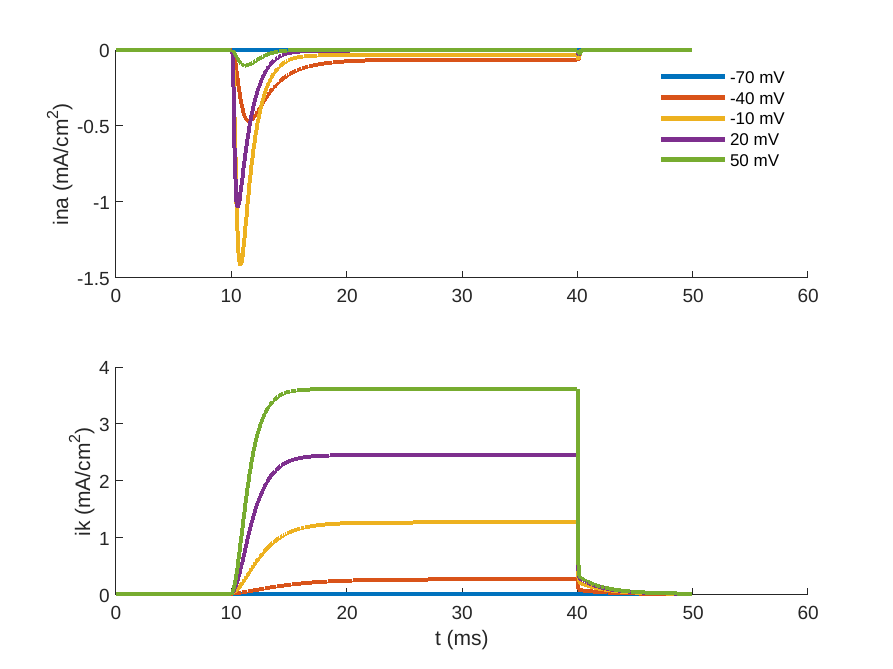

for amp2 = -70:30:50
    seclamp.amp2 = amp2;
    n.finitialize(-65);
    n.continuerun(50);
    subplot(2, 1, 1);
    plot(t.data(), ina.data(), 'linewidth', 2, "DisplayName", "" + amp2 + " mV");
    hold on;
    subplot(2, 1, 2);
    plot(t.data(), ik.data(), 'linewidth', 2);
    hold on;
end
subplot(2, 1, 1);
ylabel("ina (mA/cm^2)");
legend();
legend boxoff;
box off;
hold off;
subplot(2, 1, 2);
ylabel("ik (mA/cm^2)");
xlabel("t (ms)");
box off;
hold off;